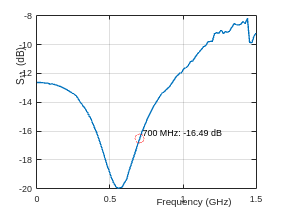

% Function to find the nearest frequency index
function idx = findNearestFreq(freqs, targetFreq)
    [~, idx] = min(abs(freqs - targetFreq));
end

% Target frequency for pointer (700 MHz)
target_freq = 700e6; % 700 MHz in Hz

% -------------------------
% OFF BIASING
% -------------------------
S_off = sparameters('lab6_amplifier_OFF_biasing.s2p');
freq_off = S_off.Frequencies;

% Extract S-parameters
S11_off = squeeze(S_off.Parameters(1,1,:));
S21_off = squeeze(S_off.Parameters(2,1,:));

% Convert to dB
S11_off_dB = 20*log10(abs(S11_off));
S21_off_dB = 20*log10(abs(S21_off));

% Find index closest to 700 MHz
idx_700MHz_off = findNearestFreq(freq_off, target_freq);
S11_at_700MHz_off = S11_off_dB(idx_700MHz_off);
S21_at_700MHz_off = S21_off_dB(idx_700MHz_off);

% Plot S11
figure('Name','OFF Biasing - S11');
plot(freq_off/1e9, S11_off_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{11} (dB)');
title('Amplifier OFF Biasing - S_{11}');
hold on;
plot(freq_off(idx_700MHz_off)/1e9, S11_at_700MHz_off, 'ro', 'MarkerSize', 10);
text(freq_off(idx_700MHz_off)/1e9, S11_at_700MHz_off, [' 700 MHz: ' num2str(S11_at_700MHz_off, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

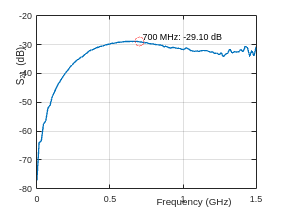


% Plot S21
figure('Name','OFF Biasing - S21');
plot(freq_off/1e9, S21_off_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{21} (dB)');
title('Amplifier OFF Biasing - S_{21}');
hold on;
plot(freq_off(idx_700MHz_off)/1e9, S21_at_700MHz_off, 'ro', 'MarkerSize', 10);
text(freq_off(idx_700MHz_off)/1e9, S21_at_700MHz_off, [' 700 MHz: ' num2str(S21_at_700MHz_off, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

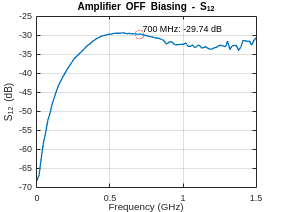


% ========================================================
% OFF BIASING - SWAPPED S22, S12
% ========================================================
S_off_SWAP = sparameters('lab6_amplifier_OFF_SWAP_biasing.s2p');
freq_off_SWAP = S_off_SWAP.Frequencies;

% Extract S-parameters
S12_off = squeeze(S_off_SWAP.Parameters(2,1,:)); % This is actually S12 in your measurement
S22_off = squeeze(S_off_SWAP.Parameters(1,1,:)); % This is actually S22 in your measurement

% Convert to dB
S12_off_dB = 20*log10(abs(S12_off));
S22_off_dB = 20*log10(abs(S22_off));

% Find index closest to 700 MHz
idx_700MHz_off_SWAP = findNearestFreq(freq_off_SWAP, target_freq);
S12_at_700MHz_off = S12_off_dB(idx_700MHz_off_SWAP);
S22_at_700MHz_off = S22_off_dB(idx_700MHz_off_SWAP);

% Plot S12
figure('Name','OFF Biasing - S12');
plot(freq_off_SWAP/1e9, S12_off_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{12} (dB)');
title('Amplifier OFF Biasing - S_{12}');
hold on;
plot(freq_off_SWAP(idx_700MHz_off_SWAP)/1e9, S12_at_700MHz_off, 'ro', 'MarkerSize', 10);
text(freq_off_SWAP(idx_700MHz_off_SWAP)/1e9, S12_at_700MHz_off, [' 700 MHz: ' num2str(S12_at_700MHz_off, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

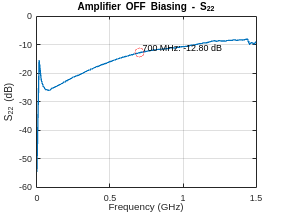


% Plot S22
figure('Name','OFF Biasing - S22');
plot(freq_off_SWAP/1e9, S22_off_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{22} (dB)');
title('Amplifier OFF Biasing - S_{22}');
hold on;
plot(freq_off_SWAP(idx_700MHz_off_SWAP)/1e9, S22_at_700MHz_off, 'ro', 'MarkerSize', 10);
text(freq_off_SWAP(idx_700MHz_off_SWAP)/1e9, S22_at_700MHz_off, [' 700 MHz: ' num2str(S22_at_700MHz_off, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

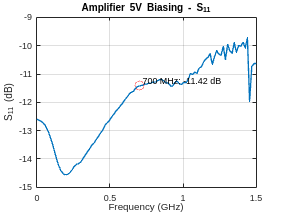


% -------------------------
% 5V BIASING
% -------------------------
S_5V = sparameters('lab6_amplifier_5V_biasing.s2p');
freq_5V = S_5V.Frequencies;

% Extract S-parameters
S11_5V = squeeze(S_5V.Parameters(1,1,:));
S21_5V = squeeze(S_5V.Parameters(2,1,:));

% Convert to dB
S11_5V_dB = 20*log10(abs(S11_5V));
S21_5V_dB = 20*log10(abs(S21_5V));

% Find index closest to 700 MHz
idx_700MHz_5V = findNearestFreq(freq_5V, target_freq);
S11_at_700MHz_5V = S11_5V_dB(idx_700MHz_5V);
S21_at_700MHz_5V = S21_5V_dB(idx_700MHz_5V);

% Plot S11
figure('Name','5V Biasing - S11');
plot(freq_5V/1e9, S11_5V_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{11} (dB)');
title('Amplifier 5V Biasing - S_{11}');
hold on;
plot(freq_5V(idx_700MHz_5V)/1e9, S11_at_700MHz_5V, 'ro', 'MarkerSize', 10);
text(freq_5V(idx_700MHz_5V)/1e9, S11_at_700MHz_5V, [' 700 MHz: ' num2str(S11_at_700MHz_5V, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

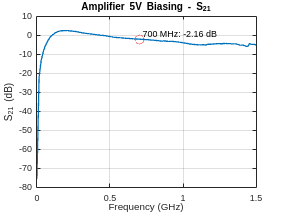


% Plot S21
figure('Name','5V Biasing - S21');
plot(freq_5V/1e9, S21_5V_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{21} (dB)');
title('Amplifier 5V Biasing - S_{21}');
hold on;
plot(freq_5V(idx_700MHz_5V)/1e9, S21_at_700MHz_5V, 'ro', 'MarkerSize', 10);
text(freq_5V(idx_700MHz_5V)/1e9, S21_at_700MHz_5V, [' 700 MHz: ' num2str(S21_at_700MHz_5V, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

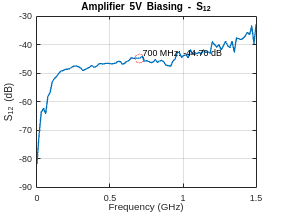


% ========================================================
% 5V BIASING - SWAPPED S22, S12
% ========================================================
S_5V_SWAP = sparameters('lab6_amplifier_5V_SWAP_biasing.s2p');
freq_5V_SWAP = S_5V_SWAP.Frequencies;

% Extract S-parameters
S12_5V = squeeze(S_5V_SWAP.Parameters(2,1,:));
S22_5V = squeeze(S_5V_SWAP.Parameters(1,1,:));

% Convert to dB
S12_5V_dB = 20*log10(abs(S12_5V));
S22_5V_dB = 20*log10(abs(S22_5V));

% Find index closest to 700 MHz
idx_700MHz_5V_SWAP = findNearestFreq(freq_5V_SWAP, target_freq);
S12_at_700MHz_5V = S12_5V_dB(idx_700MHz_5V_SWAP);
S22_at_700MHz_5V = S22_5V_dB(idx_700MHz_5V_SWAP);

% Plot S12
figure('Name','5V Biasing - S12');
plot(freq_5V_SWAP/1e9, S12_5V_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{12} (dB)');
title('Amplifier 5V Biasing - S_{12}');
hold on;
plot(freq_5V_SWAP(idx_700MHz_5V_SWAP)/1e9, S12_at_700MHz_5V, 'ro', 'MarkerSize', 10);
text(freq_5V_SWAP(idx_700MHz_5V_SWAP)/1e9, S12_at_700MHz_5V, [' 700 MHz: ' num2str(S12_at_700MHz_5V, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

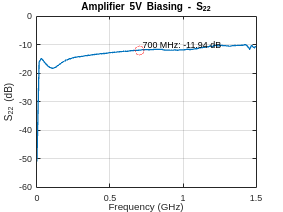


% Plot S22
figure('Name','5V Biasing - S22');
plot(freq_5V_SWAP/1e9, S22_5V_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{22} (dB)');
title('Amplifier 5V Biasing - S_{22}');
hold on;
plot(freq_5V_SWAP(idx_700MHz_5V_SWAP)/1e9, S22_at_700MHz_5V, 'ro', 'MarkerSize', 10);
text(freq_5V_SWAP(idx_700MHz_5V_SWAP)/1e9, S22_at_700MHz_5V, [' 700 MHz: ' num2str(S22_at_700MHz_5V, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

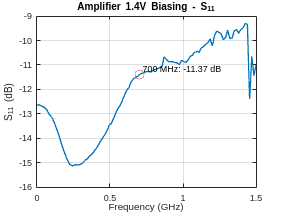


% -------------------------
% 1.4V BIASING
% -------------------------
S_1V4 = sparameters('lab6_amplifier_1.4V_biasing.s2p');
freq_1V4 = S_1V4.Frequencies;

% Extract S-parameters
S11_1V4 = squeeze(S_1V4.Parameters(1,1,:));
S21_1V4 = squeeze(S_1V4.Parameters(2,1,:));

% Convert to dB
S11_1V4_dB = 20*log10(abs(S11_1V4));
S21_1V4_dB = 20*log10(abs(S21_1V4));

% Find index closest to 700 MHz
idx_700MHz_1V4 = findNearestFreq(freq_1V4, target_freq);
S11_at_700MHz_1V4 = S11_1V4_dB(idx_700MHz_1V4);
S21_at_700MHz_1V4 = S21_1V4_dB(idx_700MHz_1V4);

% Plot S11
figure('Name','1.4V Biasing - S11');
plot(freq_1V4/1e9, S11_1V4_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{11} (dB)');
title('Amplifier 1.4V Biasing - S_{11}');
hold on;
plot(freq_1V4(idx_700MHz_1V4)/1e9, S11_at_700MHz_1V4, 'ro', 'MarkerSize', 10);
text(freq_1V4(idx_700MHz_1V4)/1e9, S11_at_700MHz_1V4, [' 700 MHz: ' num2str(S11_at_700MHz_1V4, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

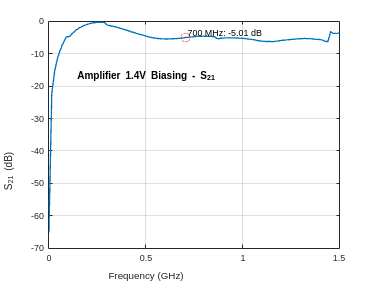


% Plot S21
figure('Name','1.4V Biasing - S21');
plot(freq_1V4/1e9, S21_1V4_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{21} (dB)');
title('Amplifier 1.4V Biasing - S_{21}');
hold on;
plot(freq_1V4(idx_700MHz_1V4)/1e9, S21_at_700MHz_1V4, 'ro', 'MarkerSize', 10);
text(freq_1V4(idx_700MHz_1V4)/1e9, S21_at_700MHz_1V4, [' 700 MHz: ' num2str(S21_at_700MHz_1V4, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

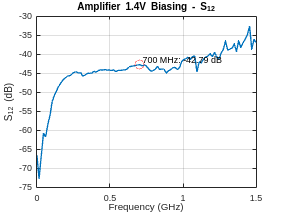


% ========================================================
% 1.4V BIASING - SWAPPED S22, S12
% ========================================================
S_1V4_SWAP = sparameters('lab6_amplifier_1.4V_SWAP_biasing.s2p');
freq_1V4_SWAP = S_1V4_SWAP.Frequencies;

% Extract S-parameters
S12_1V4 = squeeze(S_1V4_SWAP.Parameters(2,1,:));
S22_1V4 = squeeze(S_1V4_SWAP.Parameters(1,1,:));

% Convert to dB
S12_1V4_dB = 20*log10(abs(S12_1V4));
S22_1V4_dB = 20*log10(abs(S22_1V4));

% Find index closest to 700 MHz
idx_700MHz_1V4_SWAP = findNearestFreq(freq_1V4_SWAP, target_freq);
S12_at_700MHz_1V4 = S12_1V4_dB(idx_700MHz_1V4_SWAP);
S22_at_700MHz_1V4 = S22_1V4_dB(idx_700MHz_1V4_SWAP);

% Plot S12
figure('Name','1.4V Biasing - S12');
plot(freq_1V4_SWAP/1e9, S12_1V4_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{12} (dB)');
title('Amplifier 1.4V Biasing - S_{12}');
hold on;
plot(freq_1V4_SWAP(idx_700MHz_1V4_SWAP)/1e9, S12_at_700MHz_1V4, 'ro', 'MarkerSize', 10);
text(freq_1V4_SWAP(idx_700MHz_1V4_SWAP)/1e9, S12_at_700MHz_1V4, [' 700 MHz: ' num2str(S12_at_700MHz_1V4, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;

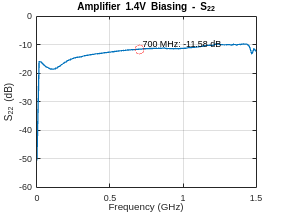


% Plot S22
figure('Name','1.4V Biasing - S22');
plot(freq_1V4_SWAP/1e9, S22_1V4_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{22} (dB)');
title('Amplifier 1.4V Biasing - S_{22}');
hold on;
plot(freq_1V4_SWAP(idx_700MHz_1V4_SWAP)/1e9, S22_at_700MHz_1V4, 'ro', 'MarkerSize', 10);
text(freq_1V4_SWAP(idx_700MHz_1V4_SWAP)/1e9, S22_at_700MHz_1V4, [' 700 MHz: ' num2str(S22_at_700MHz_1V4, '%.2f') ' dB'], 'VerticalAlignment', 'bottom');
hold off;